video = VideoReader("bird flying.mp4")

video =   VideoReader with properties:

   General Properties:
            Name: 'bird flying.mp4'
            Path: 'C:\Users\21692\Desktop\Etudes en France\IMT\FISEA2\Computer Vision\Project\Bird flying'
        Duration: 29.5883
     CurrentTime: 0
       NumFrames: <Calculating...> learn more

   Video Properties:
           Width: 640
          Height: 360
       FrameRate: 23.9760
    BitsPerPixel: 24
     VideoFormat: 'RGB24'



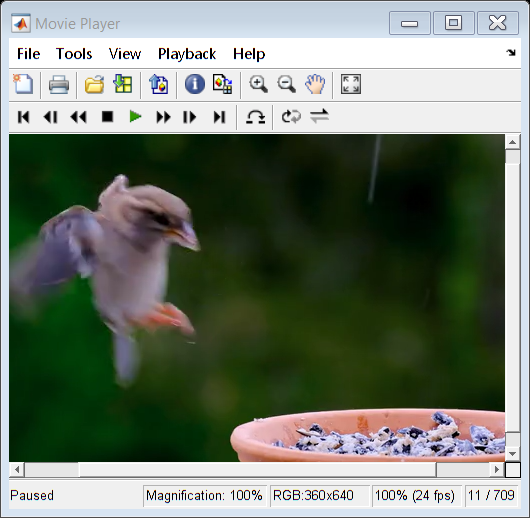

implay("bird flying.mp4")

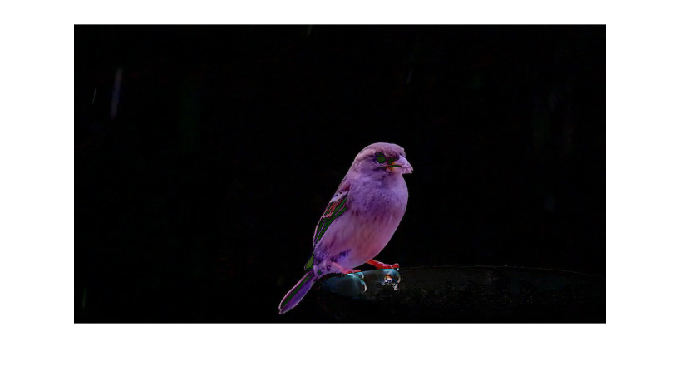

bg_bird = im2double(read(video,1));
frame_30 = im2double(read(video,30));
substracted = abs(frame_30-bg_bird);
imshow(substracted)

frame = read(video,481);
frame_bg = abs(im2double(frame) - bg_bird);
[BW_481,maskedImage] = segmentBird(frame_bg);

numFrames_bird= video.NumFrames;
v_seg= VideoWriter("Video_bird_processed","MPEG-4");

v_seg.FrameRate = video.FrameRate;
v_seg_comb.FrameRate = video.FrameRate;
%open(v_seg);
bboxes = [];
idxes = [];
for i = 6 : numFrames_bird
    frame = read(video,i);
    idx = string(i);
    while strlength(idx) ~= 3
        idx = append("0",idx);
    end
    %imwrite(frame,"BirdFlying-"+idx+".png");
    frame_bg = abs(im2double(frame) - bg_bird);
    [BW,maskedImage] = segmentBird(frame_bg);
    BW = filterLittleRegionsBird(BW);
    %imwrite(BW,"Masked-BirdFlying-"+idx+".png");
    props = regionprops("table",BW,"BoundingBox");
    BoxedBirds =insertShape(frame,"Rectangle",props.BoundingBox,"LineWidth",3,"Color","yellow");
    %writeVideo(v_seg, BoxedBirds);
    bboxes = [bboxes;props];
    idxes = [idxes;i];

end
%close(v_seg);

coords=[];
coords.frames= idxes;
coords.x1 = bboxes.BoundingBox(:,1);
coords.y1 = bboxes.BoundingBox(:,2);
coords.w = bboxes.BoundingBox(:,3);
coords.h = bboxes.BoundingBox(:,4);

coords = struct2table(coords);
writetable(coords,"coords.txt");

video =   VideoReader with properties:

   General Properties:
            Name: 'bird flying.mp4'
            Path: 'C:\Users\21692\Desktop\Etudes en France\IMT\FISEA2\Computer Vision\Project'
        Duration: 29.5883
     CurrentTime: 0
       NumFrames: 709

   Video Properties:
           Width: 640
          Height: 360
       FrameRate: 23.9760
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


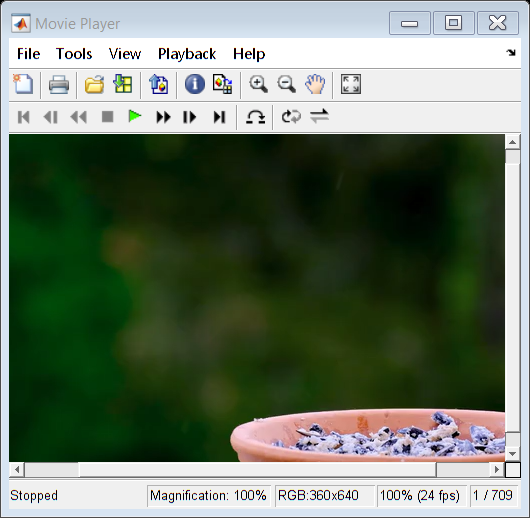

substracted = substracted(:,:,1) =

    0.0078    0.0039    0.0039    0.0039         0         0    0.0039    0.0039         0         0         0         0         0         0         0         0    0.0039    0.0039         0    0.0039         0         0    0.0039    0.0039         0         0         0         0         0         0         0         0         0    0.0039    0.0039         0         0    0.0039         0         0    0.0039    0.0039         0    0.0039    0.0039    0.0039    0.0078    0.0039         0         0         0         0         0         0         0         0         0         0         0         0    0.0039         0         0    0.0039         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0078    0.0078    0.0078         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0039    

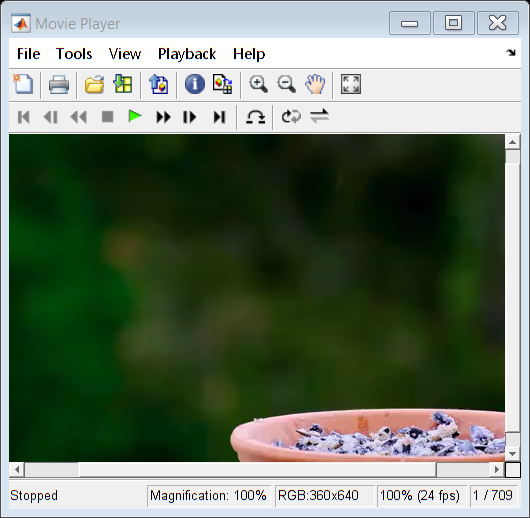

implay("Video_bird_processed.mp4")